clear all, close all, clf
%icke-linjärt sys med Newtons

x_start=[1,1,1];
%koordinater
x1=10;
x2=12;
x3=3;
y1=10;
y2=2;
y3=8;
xp=[x1,x2,x3];
yp=[y1,y2,y3];
solutions = [];
A=[ones(3,1),xp',yp'];%uppgift g
b=[x1^2+y1^2;x2^2+y2^2;x3^2+y3^2];
%vill lösa R = [X;Y;R]
R=[8;6;12];
%funktioner f
f1=@(x,y,z) (x1-x)^2+(y1-y)^2-z^2;
f2=@(x,y,z) (x2-x)^2+(y2-y)^2-z^2;
f3=@(x,y,z) (x3-x)^2+(y3-y)^2-z^2;

it=0;
t=[1;1;1];
while norm(t)>1e-9 && it<200
    x = R(1);
    y = R(2);
    r = R(3);

    F=[f1(x,y,r);f2(x,y,r);f3(x,y,r)];
    

    J=[-2*(x1-x),-2*(y1-y),-2*r;
       -2*(x2-x),-2*(y2-y),-2*r;
       -2*(x3-x),-2*(y3-y),-2*r;];
    t=J\(-F);
    R= R+t;
    it=it+1;

end

c=A\b;%uppgift g
teta = linspace(0,2*pi);
solutions = R;
x11 = R(1) + R(3)*cos(teta);
y11 = R(2) + R(3)*sin(teta);

ML=ones(4);
ML(4,:) = 3*ML(4,:);
plot(xp,yp,'*')
hold on
plot(x11,y11)
plot(R(1),R(2),'o-g')
axis equal
xlabel('x');
ylabel('y');
title('Plot av koordinater samt lösning till cirkel')
fprintf('X=%.5f\n',solutions(1));

X=7.60000


fprintf('Y=%.5f\n',solutions(2));

Y=5.15000


fprintf('R=%.5f\n',solutions(3));

R=5.41133


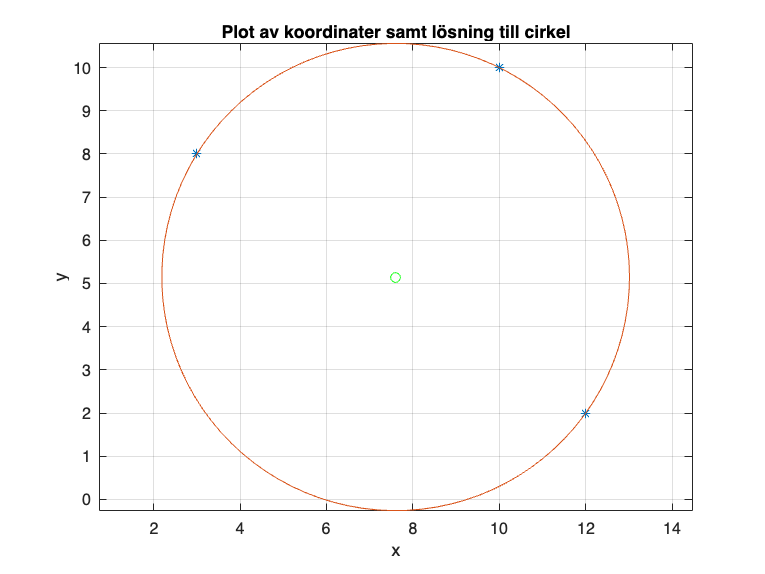

grid on